clc; clear; close all;

clear; clc; clf;

% 加载数据
load('spo2_data.mat');
referData = load('spo2_reference.mat');
spo2_reference = referData.refer4derived;

% 提取红光（R）和红外光（IR）信号
R = trace(1, :);
IR = trace(3, :);

% 初始化参数
fs = 60;  % 采样频率 60 Hz
window_size = 10 * fs;  % 窗口大小为10秒（600个样本点）
bandpass_range = [0.6 3];  % 带通滤波器的频率范围从0.6 Hz到3 Hz
[b, a] = butter(4, bandpass_range/(fs/2), 'bandpass');  % 创建带通滤波器

% 初始化结果存储数组
results = [];

% 使用滑动窗口方法计算SpO2
for i = 1:window_size:length(R) - window_size
    % 截取当前窗口的信号
    R_window = R(i:i+window_size-1);
    IR_window = IR(i:i+window_size-1);
    
    % 应用滤波器
    R_filtered = filtfilt(b, a, R_window);
    IR_filtered = filtfilt(b, a, IR_window);

    % 去除均值
    R_filtered = R_filtered - mean(R_filtered);
    IR_filtered = IR_filtered - mean(IR_filtered);

    % 查找峰值和谷值
    [pks_R, ~] = findpeaks(R_filtered);
    [vls_R, ~] = findpeaks(-R_filtered);
    vls_R = -vls_R;
    [pks_IR, ~] = findpeaks(IR_filtered);
    [vls_IR, ~] = findpeaks(-IR_filtered);
    vls_IR = -vls_IR;

    % 计算交流成分 (AC)
    AC_R = median(pks_R) - median(vls_R);
    AC_IR = median(pks_IR) - median(vls_IR);

    % 计算Ra值
    Ra = AC_R / AC_IR;

    % 根据Ra值计算SpO2
    SpO2 = 104 - (100 / 3.4) * Ra;

    % 存储结果
    results = [results, SpO2];
end

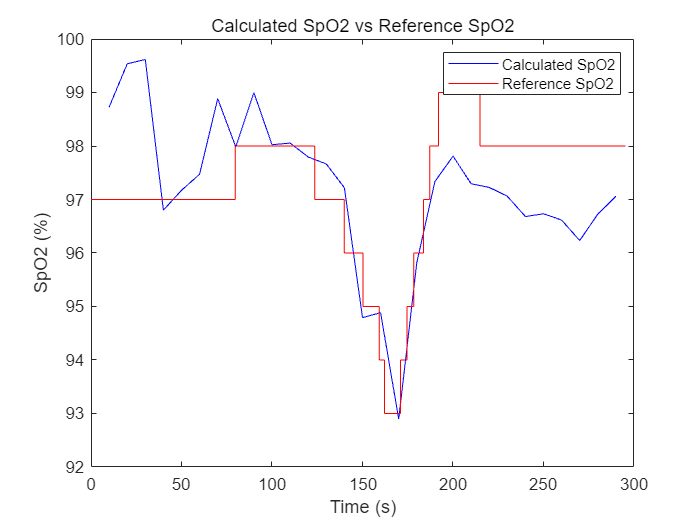

% 结果绘制
time = (1:length(results)) * (window_size / fs);
reference_time = (1:length(spo2_reference)) * (length(R) / length(spo2_reference) / fs);
figure;
plot(time, results, 'b', 'DisplayName', 'Calculated SpO2');
hold on;
plot(reference_time, spo2_reference, 'r', 'DisplayName', 'Reference SpO2');
xlabel('Time (s)');
ylabel('SpO2 (%)');
legend show;
title('Calculated SpO2 vs Reference SpO2');
hold off;